# MATLAB MPC

A, Desbiens, March 2021

clear;

## Plant model

Ts = 5; % Sampling period
s = tf('s');
Gp = -0.05 / s;  % tank model
G = ss(Gp);
% An input disturbance on each input:
%      dx/dt = Ax + [B B]*[u; du]
%          y = Cx + [D D]*[u; du]
Gcont = ss(G.A,[G.B G.B],G.C,[G.D G.D]);
model = c2d(Gcont,Ts,'zoh');
model = absorbDelay(model);    % Inset delays within the discrete state-space matrices 
model = minreal(model);
%
n = length(model.A);
nu = size(model.B,2)/2; % number of MVs
ny = size(model.C,1);

## Design MPC Controller

mpcverbosity off;
% Define types of input signals for the plant:
model = setmpcsignals(model, ...
    'MV',1:1, ... % manipulated variables
    'UD',2:2, ... % unmeasured disturbances
    'MO',1:1 ... % measured outputs
);
% Create the controller object with sampling period (all other parameters by default)
mpcobj = mpc(model,Ts);


Cost function

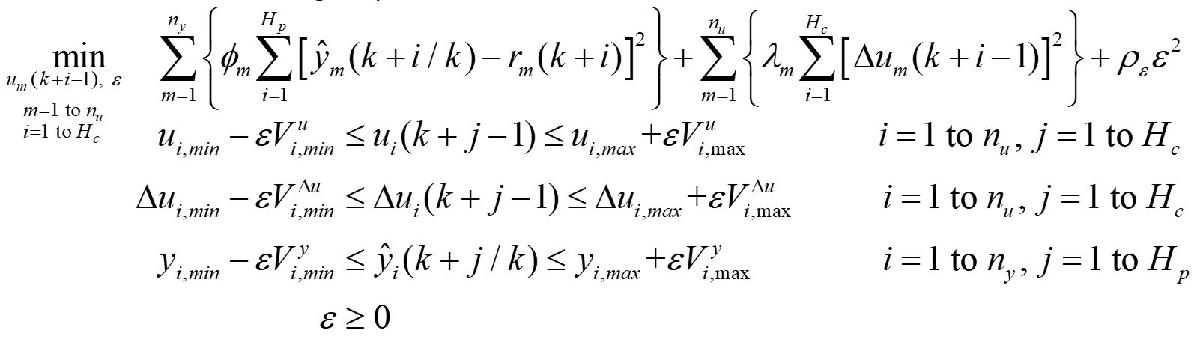

% Main MPC parameters:
%
% Operating points
u_op = [40; 0];
y_op = 60;
mpcobj.model.Nominal.U = u_op;
mpcobj.model.Nominal.Y = y_op;
%
% Prediction and control horizons
mpcobj.PredictionHorizon = 200;
mpcobj.ControlHorizon = 3;
%
% Constraints and scaling for Mvs
mpcobj.MV = struct('Min',{0},'Max',{100}, ... % u_min u_max
                   'RateMin',{-inf},'RateMax',{inf}, ... % deltau_min  deltau_max
                   'RateMinECR',{0},'RateMaxECR',{0}, ... % V^deltau_min V^deltau_max (0 = hard constraints)
                   'MinECR',{0},'MaxECR',{0}, ... % V^u_min V^u_max  (0 = hard constraints)
                   'ScaleFactor',{100}); % range of u
%
%constraints and scaling for OVs (OV = OutputVariables = MO + UO - here we only have MOs)
mpcobj.OV = struct('Min',{10},'Max',{90}, ... %y_min y_max
                   'MinECR',{0},'MaxECR',{0}, ...% V^y_min V^y_max (1 = soft constraints)
                   'ScaleFactor',{100}); ... % range of y      
% Weights
mpcobj.Weights.OutputVariables = 1; % phi
mpcobj.Weights.ManipulatedVariablesRate = 25; % lambda
mpcobj.Weights.ECR = 1e5; % rho_epsilon

## Design Observer

Some possible ways: 

1: Default observer with input disturbances = integrators driven by white noise with unitary standard deviations 

2: Default observer with integrators driven by white noise with selected standard deviations 

3: Design of our own Luenberger observer 

4: Design of our own steady-state Kalman filter:

observer=2;
% Get output scaling factors
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%sy=[mpcobj.OV(1).ScaleFactor,mpcobj.OV(2).ScaleFactor];
switch observer
    case 1
        setindist(mpcobj,'integrators'); % input disturbances are integrated white noises
    case 2
        % 2a: modindist: model of input disturbances driven by white noise
        % identical to case 1
        modindist=tf(0.1,[1 0]);
        % 2b: faster input disturbance rejection
        %modindist=tf(5,[1 0]); 
        setindist(mpcobj,'model',modindist);
    case 3
        % augmented model with integrators
        Aaug=[model.A model.B(:,1:nu); zeros(nu,n) eye(nu)];
        Caug=[model.C zeros(ny,nu)];
        %
        % poles_obs: poles of the estimation error dynamics  
        poles_obs=zeros(1,n+nu);
        for i=1:n+nu
            poles_obs(i)=1-i*0.015; % slower disturbance rejection, less sensitive to noise
        end
        %for i=1:n+ny
        %    poles_obs(i)=0.95-i*0.015; % faster disturbance rejection, more sensitive to noise
        %end
        % not obvious to know which modes affect which outputs: we would
        % need a modal observer
        %
        Kpred = place(Aaug',Caug',poles_obs)';
        setEstimator(mpcobj,Kpred);
    case 4
        % augmented model with integrators
        Aaug=[model.A model.B(:,1:nu); zeros(nu,n) eye(nu)];
        Baug=[model.B(:,1:nu); zeros(nu,nu)];
        Caug=[model.C zeros(ny,nu)];
        Daug=[zeros(ny,nu)];       
        %
        % Matrices G and H: seek help kalman 
        G=eye(size(Baug,1));
        H=zeros(size(Caug,1),size(Baug,1));
        %
        % Covariance matrices
        R=0.1*eye(ny); % Measurement noise
        % Q: covariance matrix, process noise
        Q=blkdiag(0.1*eye(n-nu),0.001,0.001);      
        %Q=blkdiag(eye(n-nu),0.001,1); 
        %Q=blkdiag(eye(n-nu),1,0.001); 
        %Q=blkdiag(eye(n-nu),1,1); 
        %
        [~,Kpred] = kalman(ss(Aaug,[Baug G],Caug,[Daug H],Ts),Q,R);
        setEstimator(mpcobj,Kpred);
end

% The creation of the model predictive controller object «mpcobj» is now complete:
save("mpcobj.mat","mpcobj")
mpcobj

 
MPC object (created on 26-May-2023 20:13:11):
---------------------------------------------
Sampling time:      5 (seconds)
Prediction Horizon: 200
Control Horizon:    3

Plant Model:        
                                      --------------
      1  manipulated variable(s)   -->|  1 states  |
                                      |            |-->  1 measured output(s)
      0  measured disturbance(s)   -->|  2 inputs  |
                                      |            |-->  0 unmeasured output(s)
      1  unmeasured disturbance(s) -->|  1 outputs |
                                      --------------
Indices:
  (input vector)    Manipulated variables: [1 ]
                  Unmeasured disturbances: [2 ]
  (output vector)        Measured outputs: [1 ]

Disturbance and Noise Models:
        Output disturbance model: default (type "getoutdist(mpcobj)" for details)
         Input disturbance model: user specified (type "getindist(mpcobj)" for more details)
         Measurement noi


return

## Simulation with Simulink

Tstop = 2400;          % simulation time
t = 0:Ts:Tstop-Ts;      % time vector
N = length(t);        % number of simulation steps
%
% Setpoints
r = 60+[zeros(50,1); -10*ones(N-50,1)];                     
%
% Input and output disturbances
du = [zeros(2*N/6,1); -15*ones(N-2*N/6,1)];                   
dy = [zeros(4*N/6,1); 15*ones(N-4*N/6,1)]; 
%
% Simulink
r_sim = [t' r];
du_sim = [t' du];
dy_sim = [t' dy];
open('MPC_Matlab_sim.slx');
sim('MPC_Matlab_sim.slx');

# ADVANCED CODE FOR GEL-7029:

## Simulate Closed-Loop Response Using the SIM Command

% Specify simulation parameters.
SimOptions = mpcsimopt(mpcobj);                       
SimOptions.UnmeasuredDisturbance = du;
SimOptions.OutputNoise = dy;
SimOptions.ShowOutputNoise = 1;    % Does not work...
%
% Run the closed-loop simulation and save the results.
[y,tsim,u,xp] = sim(mpcobj,N,r,[],SimOptions);
%
% Plot results.
figure(1);
subplot(211)
plot(tsim,y,'k-',tsim,r,'r:','linewidth',2)
title('Set-points and CVs (sim)');
text(300,40,'Problem with sim'); % The same problem is present when simulating inside mpcDesigner (it uses sim command)
text(300,37,'with output'); 
text(300,34,'disturbances');
grid
subplot(212)
stairs(tsim,u,'k-','linewidth',2)
title('MVs');
grid

## Simulate MPC with MPCMOVE (for loop)

% First get the discrete-time state-space matrices of the plant.
[A,B,C,D] = ssdata(model);
x = zeros(n,1);                 % Initial state of the plant
u = zeros(nu,1);                % Initial MVs
xmpc = mpcstate(mpcobj);    % Initial state of the MPC controller
%
% Store the closed-loop MPC trajectories in arrays YY,UU.
YY=zeros(2,N);
UU=zeros(2,N);
%
% Create simulation loop
for i=1:N
    % Plant equation: output
    y = C*x + dy(i,:)' + mpcobj.model.Nominal.Y; 
    YY(:,i) = y;
    %     
    % Compute MPC action
    [u, predinfo] = mpcmove(mpcobj,xmpc,y,r(i,1:2)',[]);
    %
    % Plant equations: state update
    x = A*x + B*([u; du(i,:)'] - mpcobj.model.Nominal.U); 
    UU(:,i) = u;
end

% Plot results.
figure(2);
subplot(211)
plot(t,YY,'k-',t,r,'r:','linewidth',2)
grid
title('Set-points and CVs (mpcmove)');
subplot(212)
stairs(t',UU')
stairs(t',UU','k-','linewidth',2)
grid
title('MVs');